# Homework 1: Recognising digits

Five patterns

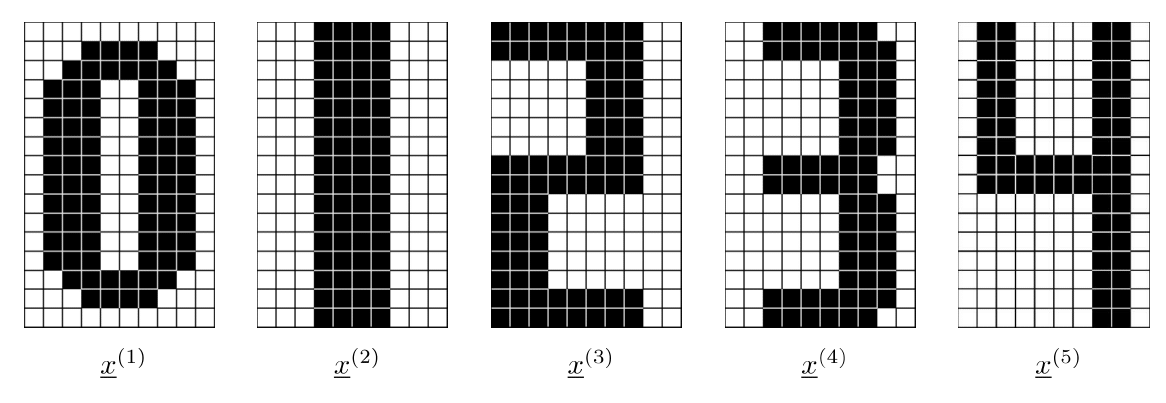

The Figure shows five patterns ��$\underline x^{(1)},\underline x^{(2)},\underline x^{(3)},\underline x^{(4)},\underline x^{(5)}$�� representing the digits 0 to 4. The patterns are binary, white bits correspond to -1, black bits to 1.

Represent these patterns as vectors to store them in a Hopfield network using Hebb's rule with$w_{ii}=0$, Eq. (2.26) in the course book. Use a typewriter scheme to index the bits, starting from the top row and going from left to right in each row.

Below you are given three different patterns to feed into your network. For each of these patterns, iterate asynchronous determistic updates of the network using the typewriter scheme. If, at some update, you encounter $\text{sgn}(0)$, then simply set $\text{sgn}(0)=1$. Stop iterating when you reach a steady state, and answer the following questions:

(A) To which pattern does your network converge?

(B) Classify this pattern using the following scheme: if the pattern you obtain correspods to any of the stored patterns $\underline x^{(\mu)}$��, enter the pattern index *μ* (for example, you enter 1 if you retrieve digit 0). If your network retrieves an inverted stored pattern, then enter −*μ* (for example, you enter -1 if you get the inverted digit 0). If you get anything else, enter 6.

## Read in the patterns to store and classify

clear
load("patterns.mat")

## Initial conditions

p = size(digit_patterns,2)

p = 5

N = size(digit_patterns,1)

N = 160

## Initalize Hopfield network

W = zeros(N);
for mu = 1:p
    W = W + digit_patterns(:,mu)*digit_patterns(:,mu)'/N;
end

% set diagonal elements to 0
for i = 1:N
    W(i,i) = 0;
end
W

W =          0    0.0188    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063    0.0188    0.0312    0.0188    0.0063   -0.0063   -0.0063   -0.0063   -0.0063    0.0063   -0.0063    0.0188    0.0188    0.0063   -0.0063   -0.0063   -0.0063    0.0063   -0.0063   -0.0063   -0.0063    0.0188    0.0188   -0.0063   -0.0063   -0.0063    0.0063    0.0188   -0.0063   -0.0063   -0.0188    0.0188    0.0188   -0.0063   -0.0063   -0.0063    0.0063    0.0188   -0.0063   -0.0063   -0.0188    0.0188
    0.0188         0    0.0188   -0.0063   -0.0063   -0.0063   -0.0063    0.0188    0.0188    0.0063    0.0188    0.0312    0.0188   -0.0188   -0.0188   -0.0188   -0.0188    0.0188    0.0063    0.0063    0.0063    0.0188    0.0063   -0.0188   -0.0188   -0.0063   -0.0188    0.0063    0.0063    0.0063    0.0063    0.0063    0.0063   -0.0188   -0.0063    0.0063   -0.0188    0.0063   -0.0063    0.0063    0.0063    0.0063    0.0063   -0.0188   -0.0063    0.0063   -0.0188    0.0063   -0.0063    0

s = test_patterns(:,1)

s =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
     1
     1


s_old = zeros(N,1);
while s_old ~= s
    s_old = s;
    for i = 1:N
        b = W(i,:)*s;
        if b == 0
            s(i) = 1;
        else
            s(i) = sign(b);
        end
    end
end
s1 = s

s1 =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
     1
     1


mtx = reshape(s1,[10,16])'

mtx =     -1    -1    -1    -1    -1    -1    -1    -1     1     1
    -1    -1    -1    -1    -1    -1    -1    -1     1     1
     1     1     1     1     1    -1    -1    -1     1     1
     1     1     1     1     1    -1    -1    -1     1     1
     1     1     1     1     1    -1    -1    -1     1     1
     1     1     1     1     1    -1    -1    -1     1     1
     1     1     1     1     1    -1    -1    -1     1     1
    -1    -1    -1    -1    -1    -1    -1    -1     1     1
    -1    -1    -1    -1    -1    -1    -1    -1     1     1
    -1    -1    -1     1     1     1     1     1     1     1


writematrix(mtx)